# Target Tracking in Highway Scenario through MHE algorithm

clear 
close all
clc

rng('default')

## Load the Data & processing

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("simulation/SimulationData");

Urban = 1; % Urban scenario
% HW_const_speed = 0; % Highway data scenario
if Urban
    load("Urban_time_vector.mat");
    load("Urban_camera_meas_array.mat");
    load("Urban_camera_speed_array.mat");
    load("Urban_radar_meas_array.mat");
    load("Urban_radar_speed_array.mat");
    load("Urban_GT_array.mat");
    load("Urban_GT_speed_array.mat");
    load("Urban_GT_state.mat");
% elseif HW_const_speed
else
    load("HW_time_vector.mat");
    load("HW_camera_meas_array.mat");
    load("HW_camera_speed_array.mat");
    load("HW_radar_meas_array.mat");
    load("HW_radar_speed_array.mat");
    load("HW_GT_array.mat");
    load("HW_GT_speed_array.mat");
    load("HW_GT_state.mat");
end

## Estimation Algorithm parameters

% Building the vector with measured data
Ts = 0.1;       % sensor sampling time
Ts_sim = 0.01;  % simulation sampling time [s]
max_time = 12; % time up to which data are good [s]
min_time = 1; % time from which good measurements [s]
max_index = max_time/Ts_sim; 
min_index = min_time/Ts_sim + 1; 

GT_state_new  = GT_state;

real_meas = 0; % set to 1 to use real sensor data

if real_meas
    % time vector
    time_vec = time_vec(~isnan(radar_meas(min_index:max_index,1)));
    % position data taken from radar
    x_pos_radar = radar_meas(~isnan(radar_meas(min_index:max_index,1)),1);
    y_pos_radar = radar_meas(~isnan(radar_meas(min_index:max_index,2)),2);
    xy_pos_radar = [x_pos_radar y_pos_radar]'; %radar_meas(min_index:max_index,1:2)'; % transpose !!!
    % position from camera
    x_pos_camera = camera_meas(~isnan(radar_meas(min_index:max_index,1)),1);
    y_pos_camera = camera_meas(~isnan(radar_meas(min_index:max_index,2)),2);
    xy_pos_camera = [x_pos_camera y_pos_camera]'; %radar_meas(min_index:max_index,1:2)'; % transpose !!!
    
    % xy_pos_camera = camera_meas(min_index:max_index,1:2)'; % transpose !!!
    
    % speed data taken from the radar sensor measurements better, camera
    % contains sparse speed sensor data
    speed_radar = radar_speed(~isnan(radar_speed(min_index:max_index)))';
    speed_camera = camera_speed(~isnan(radar_speed(min_index:max_index)))';
else
    % downsampling of measurement signals: from 0.01 select only values
    % sampled at 0.1

    % time vector
    time_vec = time_vec(~isnan(radar_meas(min_index:max_index,1)));
    
    % white noises

    % camera WN
    camera_x_noise = sqrt(1)*randn((max_time-min_time)/Ts,1);
    camera_y_noise = sqrt(0.5)*randn((max_time-min_time)/Ts,1);
    camera_v_noise = sqrt(0.5)*randn((max_time-min_time)/Ts,1);

    % radar WN
    radar_x_noise = sqrt(0.5)*randn((max_time-min_time)/Ts,1);
    radar_y_noise = sqrt(1)*randn((max_time-min_time)/Ts,1);
    radar_v_noise = sqrt(0.5)*randn((max_time-min_time)/Ts,1);

    % position data taken from radar
    GT_state = GT_state_new(min_index:max_index,:); % fundamental row
    
    x_pos_radar = GT_state(~isnan(radar_meas(min_index:max_index,1)),1); % + radar_x_noise;
    y_pos_radar = GT_state(~isnan(radar_meas(min_index:max_index,2)),2) + radar_y_noise;
    xy_pos_radar = [x_pos_radar y_pos_radar]';%radar_meas(min_index:max_index,1:2)'; % transpose !!!
    
    % position from camera
    x_pos_camera = GT_state(~isnan(radar_meas(min_index:max_index,1)),1)+ camera_x_noise;
    y_pos_camera = GT_state(~isnan(radar_meas(min_index:max_index,2)),2);%+ camera_y_noise;
    xy_pos_camera = [x_pos_camera y_pos_camera]';%radar_meas(min_index:max_index,1:2)'; % transpose !!!
    
    % xy_pos_camera = camera_meas(min_index:max_index,1:2)'; % transpose !!!
    
    % speed data taken from the radar sensor measurements better, camera
    % contains sparse speed sensor data
    speed_radar = (GT_speed(~isnan(radar_speed(min_index:max_index))))' % + radar_v_noise)';
    speed_camera = (GT_speed(~isnan(radar_speed(min_index:max_index))))' % + camera_v_noise)';
end

speed_radar =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    1.9992    1.9932    1.9830    1.9727    1.9625    1.9522    1.9419    1.9317    1.9214    1.9111    1.9008    1.8906    1.8803    1.8700    1.8598    1.8495    1.8392    1.8290    1.8187    1.8084    1.7982    1.7879    1.7776    1.7673    1.7571    1.7468    1.7365    1.7263    1.7160    1.7057    1.6955    1.6852    1.6749    1.6646    1.6544    1.6441    1.6338    1.6236    1.6133    1.6030


speed_camera =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    1.9992    1.9932    1.9830    1.9727    1.9625    1.9522    1.9419    1.9317    1.9214    1.9111    1.9008    1.8906    1.8803    1.8700    1.8598    1.8495    1.8392    1.8290    1.8187    1.8084    1.7982    1.7879    1.7776    1.7673    1.7571    1.7468    1.7365    1.7263    1.7160    1.7057    1.6955    1.6852    1.6749    1.6646    1.6544    1.6441    1.6338    1.6236    1.6133    1.6030



% building the measurement vector
ymeas_camera = [xy_pos_camera;speed_camera];
ymeas_radar = [xy_pos_radar;speed_radar];

N = length(speed_radar); % number of meas samples

## Filter

% filter parameter
nz = 5; % number of states
ny = 3; % number of measured output
nu = 2; % number of inputs (noises)

Msec            =   1; % Seconds of Moving Horizon Estimator window
M               =   round(Msec/Ts); % number of steps in the window
MHE_interval = 1; % number of steps after which optimization routine is repeated

% Covariance Matrices 
camera_x_var = 100;
camera_y_var = 1;
camera_v_var = 0.1;
R_camera = diag([camera_x_var,camera_y_var,camera_v_var])*eye(ny);

radar_x_var = 1;
radar_y_var = 100;
radar_v_var = 0.1;
R_radar = diag([radar_x_var,radar_y_var,radar_v_var])*eye(ny);

long_acc_var = 1;
ang_acc_var = 0.01;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

A_terminal = eye(nz);

z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);0.1;0.1];

% z_minus = [0;0;0;0;0];

%% Initialize optimization variables
x0 = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);0.1;0.1;        % initial state
     0.01*ones(2*M,1)];    % disturbances/input noise

% x0 = [0;0;0;0;0;        % initial state
%      zeros(2*M,1)];

**Remark: **The optimization routines require the optimization variables to be provided **as a single column vector.**

z_est = zeros(nz,N); % array to store estimated state
d_est = zeros(nu,N); % array to store estimated disturbances

% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';

Ts_sim = 0.1; % simulation time equal to sensor sampling time

tic
% estimation along the whole simulated trajectory

**Remark: **`ind` starts from M+1 because we have to fill the buffer of the filter at initialization and because matlab index arrays from 1.

for ind = M+1:MHE_interval:N
    
    myoptions.outputfcn     =   @(x)target_cost(x,M,Ts,ymeas_camera(:,ind-M:ind),ymeas_radar(:,ind-M:ind),z_minus,R_camera,R_radar,Q,A_terminal); % cost func
    
    % Run solver on window from 'ind-M' up to 'ind' step
    [xstar,~,~,~,~] = myfminunc(@(x)target_cost(x,M,Ts,ymeas_camera(:,ind-M:ind),ymeas_radar(:,ind-M:ind),z_minus,R_camera,R_radar,Q,A_terminal),x0,myoptions);
    
    % simulation of the system with optimal solution
    z_minus_M_t = xstar(1:nz,1); % z(-M|t) of current iteration, aka estimated initial state of the system
    d_course = [xstar(6:6+M-1,1)';xstar(6+M:end,1)']; % course of disturbance
    %% Run simulation with FFD
    time_FFD    =   [0:Ts_sim:M*Ts];
    Nblock      =   Ts/Ts_sim;
    Nsim_FFD    =   length(time_FFD);
    
    z_sim      =   zeros(nz,Nsim_FFD);
    z_sim(:,1) =   z_minus_M_t;
    
    % system simulation
    for iind=2:Nsim_FFD
        d                  =   d_course(:,1+floor(time_FFD(iind-1)/Ts));
        % zdot               =   CTCV_model(0,z_sim(:,iind-1),0,d,0);
        %z_sim(:,iind)      = CTRV_model_DT(z_sim(:,iind-1),d,Ts_sim);
        z_sim(:,iind)      = CTRV_exact_DT(z_sim(:,iind-1),d,Ts_sim);
        % z_sim(:,iind)       = z_sim(:,iind-1)+Ts/Nblock*zdot;
    end
    x0 = [z_sim(1,Ts/Ts_sim + 1); z_sim(2,Ts/Ts_sim + 1); z_sim(3,Ts/Ts_sim + 1);z_sim(4,Ts/Ts_sim + 1);z_sim(5,Ts/Ts_sim + 1);[xstar(7:6+M,1);0];[xstar(6+M+2:end,1)];0];
    z_est(:,ind-M) = [z_sim(1,end); z_sim(2,end); z_sim(3,end);z_sim(4,end);z_sim(5,end)]; % z(0|t)
    d_est(:,ind-M) = [d_course(1,1);d_course(2,1)]; % d(-M|t)
    z_minus = z_sim(:,Ts/Ts_sim+1); % z(-M+1|t) = z_minus(-M|t)
end

Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    1.05924e+07   1.05585e+01    1.00000e+00    1.00000e+00                0
        1    8.30687e+06   7.19097e+00    3.18943e-01    1.98112e-02                8
        2    1.34448e+06   6.54245e+00    9.01845e-02    4.68818e-03                9
        3    9.61019e+04   6.21814e+00    4.95711e-02    1.60238e-03                9
        4    7.65694e+03   6.05592e+00    2.60883e-02    1.97119e-03                8
        5    6.10025e+04   6.00182e+00    8.93378e-03    2.77004e-03                7
        6    3.62845e+01   5.98212e+00    3.28194e-03    9.33430e-04                9
        7    2.89349e+01   5.98097e+00    1.92498e-04    7.88801e-04                6
        8    3.18010e+02   5.98086e+00    1.79617e-05    1.40414e-04                7
        9    2.61567e+01   5.98076e+00    1.61317e-05    3.04561e-04                8
       10    5.88775e+02   5.97556e+00    8.70616e-04 

toc

Elapsed time is 12.710051 seconds.


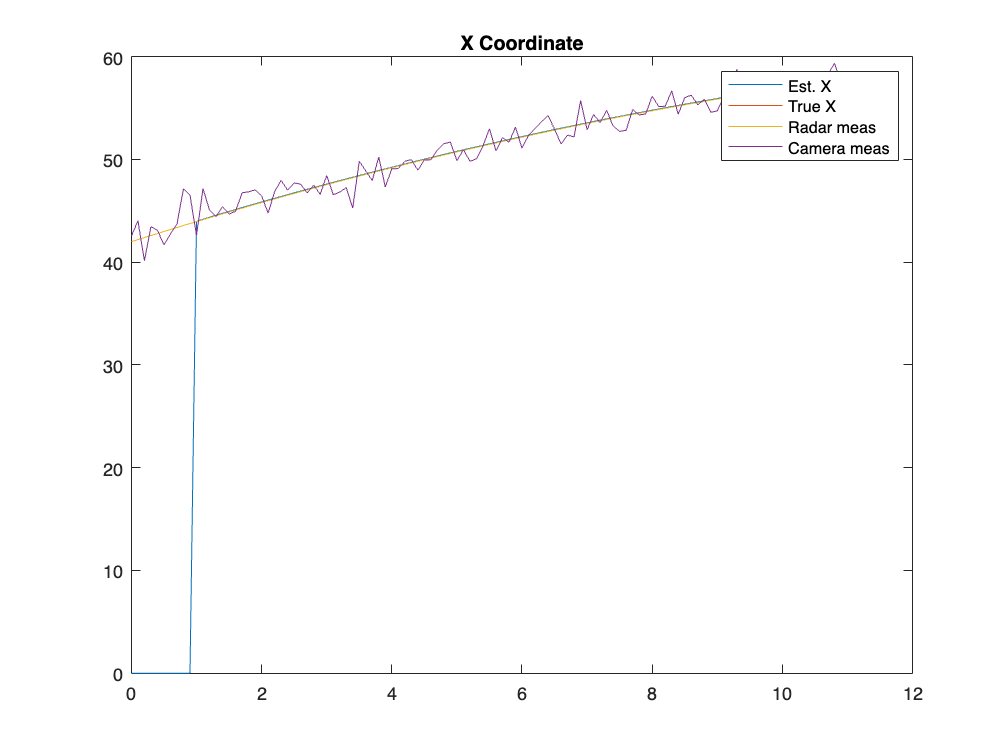

% check results against ground truth
z_est = [zeros(nz,M) z_est(:,1:end-M)];
d_est = [zeros(nu,M) d_est(:,1:end-M)];

% GT_state_plot = GT_state(~isnan(radar_meas(min_index:max_index,1)),1); 
figure(1)
plot(time_vec,z_est(1,:)), hold on
plot(time_vec,GT_state(~isnan(radar_meas(min_index:max_index,1)),1)), hold on
plot(time_vec,x_pos_radar),hold on
plot(time_vec,x_pos_camera)
title('X Coordinate')
legend('Est. X','True X','Radar meas','Camera meas')
hold off

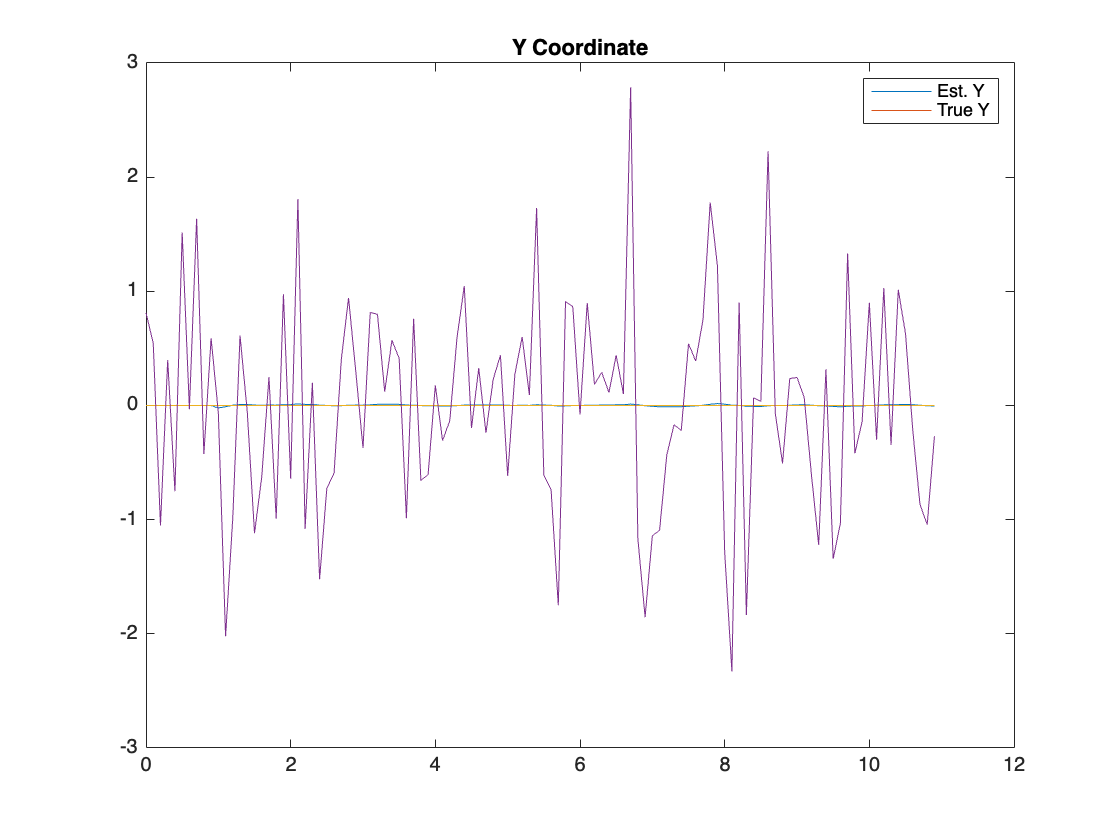


figure(2)
plot(time_vec,z_est(2,:)), hold on
plot(time_vec,GT_state(~isnan(radar_meas(min_index:max_index,1)),2)), hold on
plot(time_vec,y_pos_camera)
plot(time_vec,y_pos_radar)
title('Y Coordinate')
legend('Est. Y','True Y')
hold off

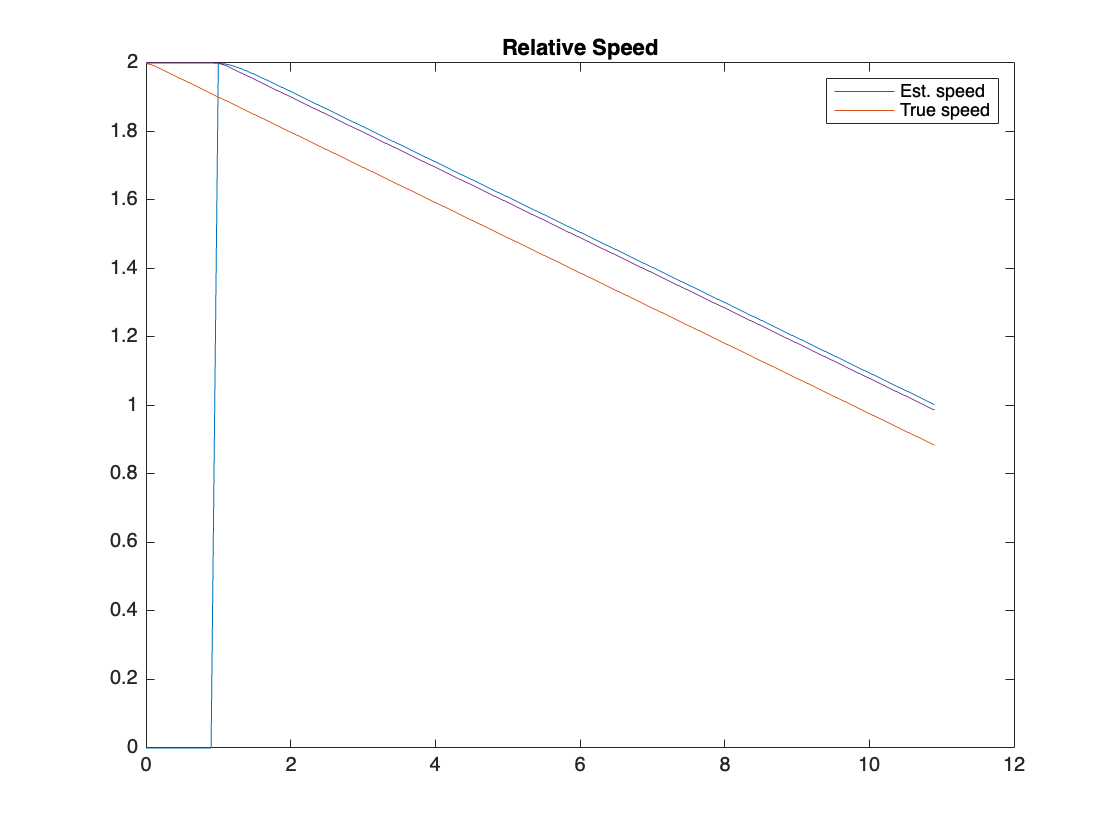

figure(3)
plot(time_vec,z_est(3,:)), hold on
plot(time_vec,GT_state(~isnan(radar_meas(min_index:max_index,1)),3)), hold on
plot(time_vec,speed_radar),hold on
plot(time_vec,speed_camera)
title('Relative Speed')
legend('Est. speed','True speed')
hold off

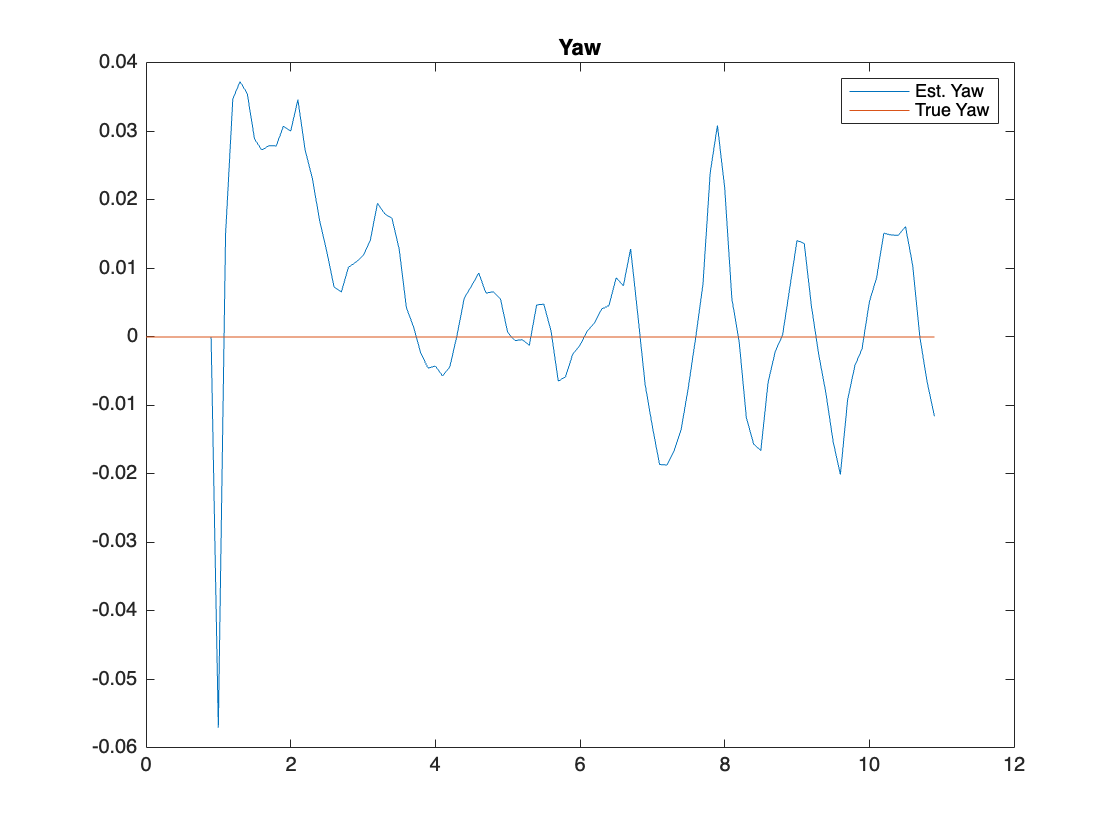

% GT_state_yaw = GT_state(min_index:max_index,4);
figure(4)
plot(time_vec,z_est(4,:)), hold on
plot(time_vec,GT_state(~isnan(radar_meas(min_index:max_index,1)),4))
title('Yaw')
legend('Est. Yaw','True Yaw')
hold off

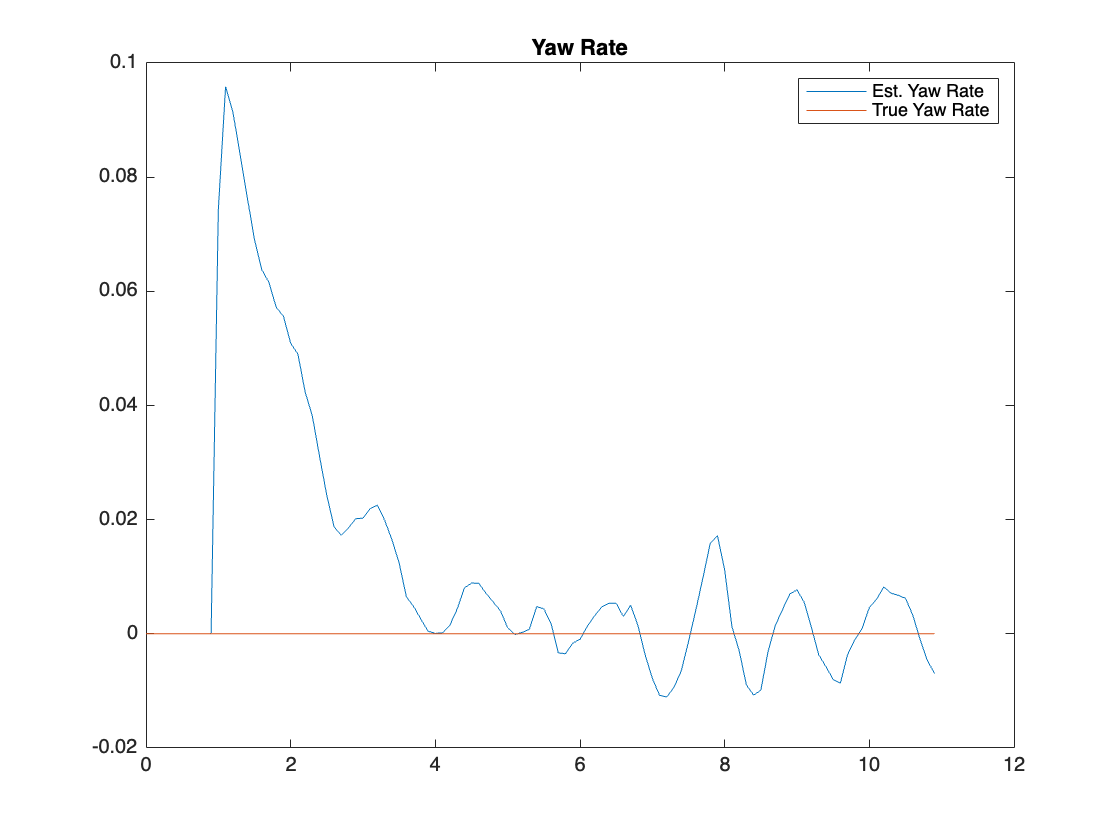

figure(5)
plot(time_vec,z_est(5,:)), hold on
plot(time_vec,GT_state(~isnan(radar_meas(min_index:max_index,1)),5))
title('Yaw Rate')
legend('Est. Yaw Rate','True Yaw Rate')
hold off

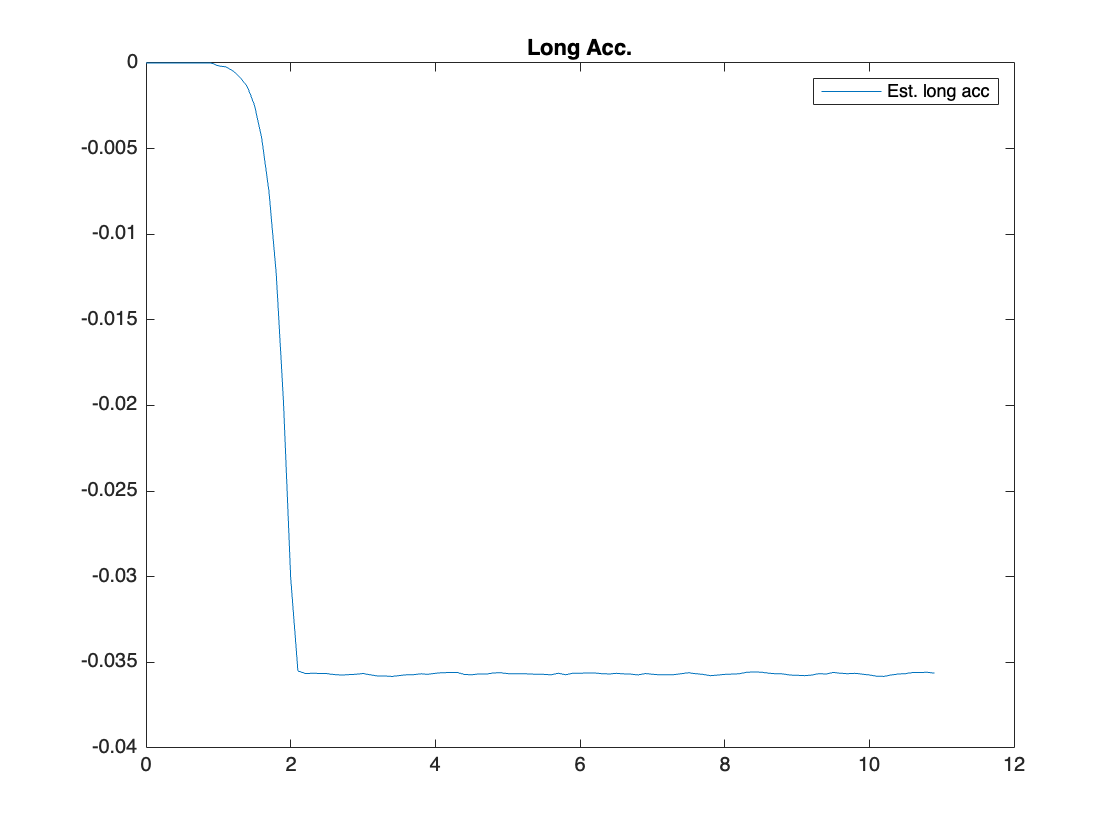

figure(6)
plot(time_vec,d_est(1,:)), hold on
%plot(GT_state(~isnan(radar_meas(min_index:max_index,1)),5))
title('Long Acc.')
legend('Est. long acc')%,'True Yaw Rate')
hold off

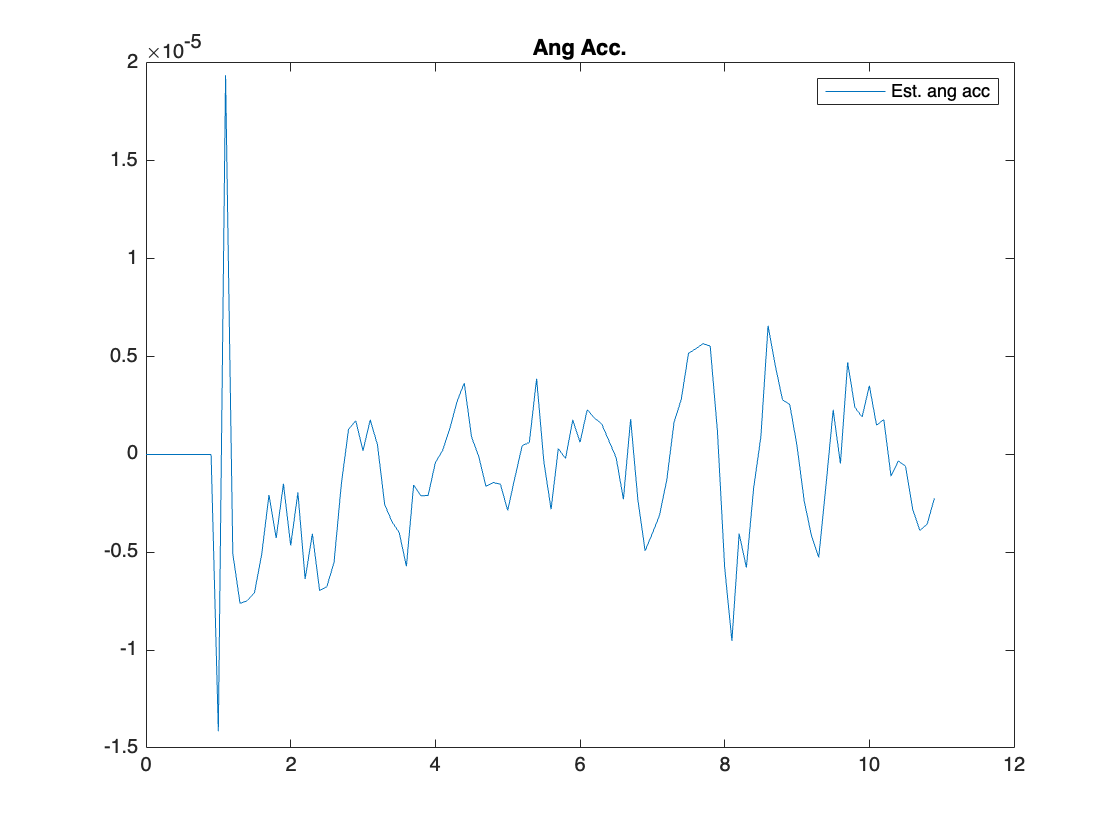

figure(7)
plot(time_vec,d_est(2,:)), hold on
% plot(GT_state(~isnan(radar_meas(min_index:max_index,1)),5))
title('Ang Acc.')
legend('Est. ang acc')%,'True Yaw Rate')
hold off